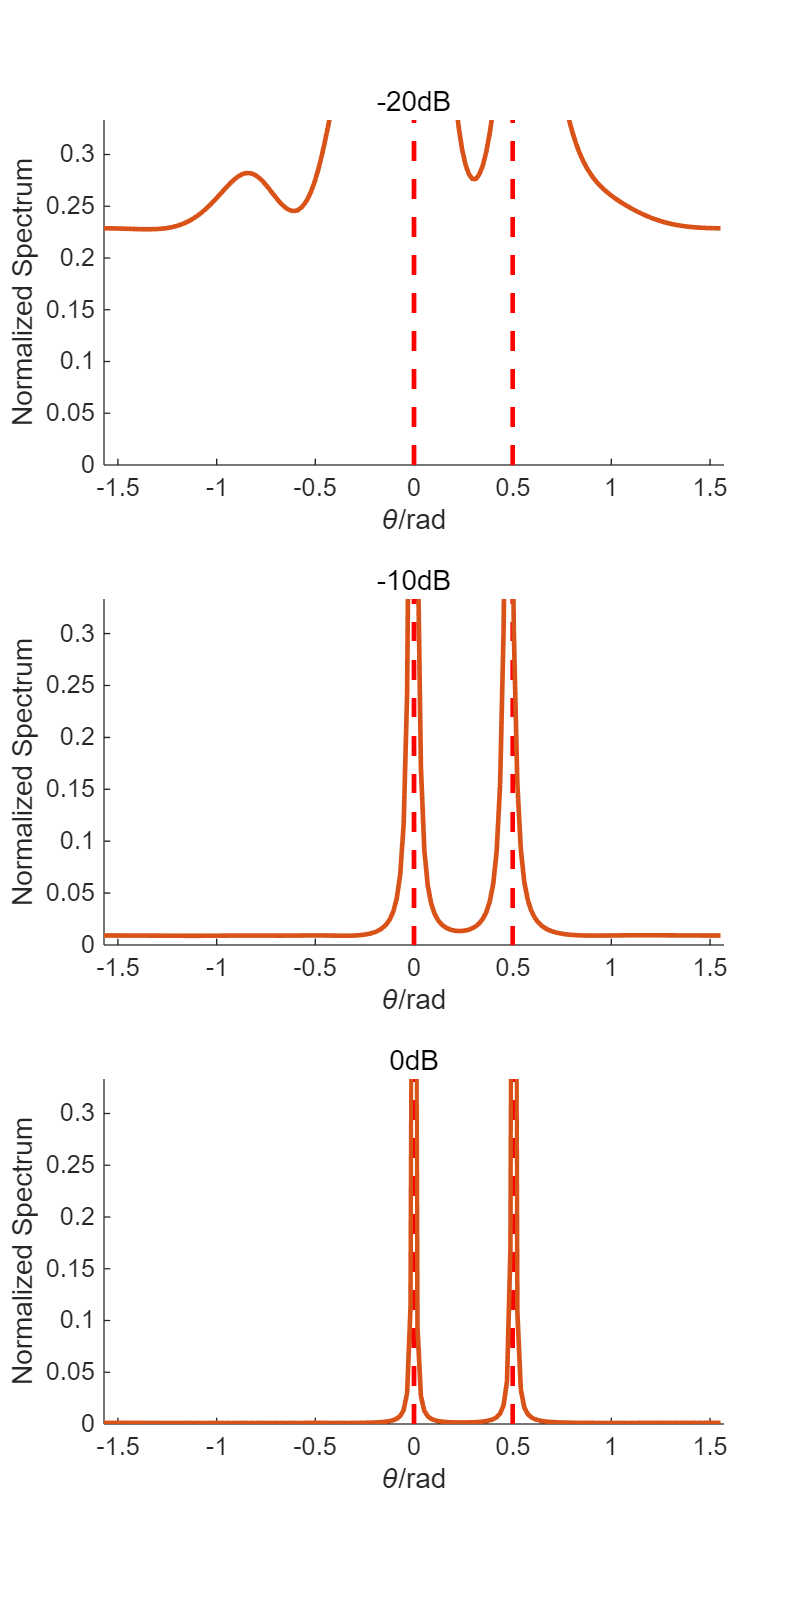

% 打开三个 .fig 文件
fig1 = openfig('MUSIC-SNR=-20dB.fig'); % 对应 50快拍
fig2 = openfig('MUSIC-SNR=-10dB.fig'); % 对应 200快拍
fig3 = openfig('MUSIC-SNR=0dB.fig'); % 对应 1000快拍

% 创建新图形窗口
figure;

% 第一个子图：50快拍（纵向排列：3行1列）
subplot(3, 1, 1);
% 获取 fig1 的 Axes 对象
axes1 = get(fig1, 'Children');
% 提取 Axes 内的绘图对象并设置属性
for i = 1:length(axes1)
    if isa(axes1(i), 'matlab.graphics.axis.Axes')
        plot_objs = get(axes1(i), 'Children'); % 获取 Axes 内的子对象
        copyobj(plot_objs, gca); % 复制绘图对象到当前 Axes
        % 提取并设置 X 和 Y 轴标签（需要获取 String 属性）
        x_label = get(axes1(i), 'XLabel');
        y_label = get(axes1(i), 'YLabel');
        if ~isempty(x_label.String)
            xlabel(x_label.String);
        end
        if ~isempty(y_label.String)
            ylabel(y_label.String);
        end
        % 设置 X 和 Y 轴范围
        xlim(get(axes1(i), 'XLim'));
        current_ylim = get(axes1(i), 'YLim');
        set(gca, 'YLim', [current_ylim(1), current_ylim(2)/3]); % 纵坐标范围调整为 1/3
    end
end
title('-20dB');

% 第二个子图：200快拍
subplot(3, 1, 2);
axes2 = get(fig2, 'Children');
for i = 1:length(axes2)
    if isa(axes2(i), 'matlab.graphics.axis.Axes')
        plot_objs = get(axes2(i), 'Children');
        copyobj(plot_objs, gca);
        x_label = get(axes2(i), 'XLabel');
        y_label = get(axes2(i), 'YLabel');
        if ~isempty(x_label.String)
            xlabel(x_label.String);
        end
        if ~isempty(y_label.String)
            ylabel(y_label.String);
        end
        xlim(get(axes2(i), 'XLim'));
        current_ylim = get(axes2(i), 'YLim');
        set(gca, 'YLim', [current_ylim(1), current_ylim(2)/3]);
    end
end
title('-10dB');

% 第三个子图：1000快拍
subplot(3, 1, 3);
axes3 = get(fig3, 'Children');
for i = 1:length(axes3)
    if isa(axes3(i), 'matlab.graphics.axis.Axes')
        plot_objs = get(axes3(i), 'Children');
        copyobj(plot_objs, gca);
        x_label = get(axes3(i), 'XLabel');
        y_label = get(axes3(i), 'YLabel');
        if ~isempty(x_label.String)
            xlabel(x_label.String);
        end
        if ~isempty(y_label.String)
            ylabel(y_label.String);
        end
        xlim(get(axes3(i), 'XLim'));
        current_ylim = get(axes3(i), 'YLim');
        set(gca, 'YLim', [current_ylim(1), current_ylim(2)/3]);
    end
end
title('0dB');

% 调整图形窗口大小（适合纵向排列）
set(gcf, 'Position', [100, 100, 400, 800]);

% 关闭原始 .fig 文件
close(fig1);
close(fig2);
close(fig3);

% 保存调整后的图形
savefig('adjusted_plots_vertical.fig'); % 保存为 .fig 文件
saveas(gcf, 'adjusted_plots_vertical.png'); % 保存为 PNG 文件